%% Include necessary packages

%IMPORTANT: set the paths of the packages inside this function!
importPackages();

DATA_PATH = 'D:\T301\T301_tmev_d1\'; %folder in which the data is located; should end with \
ND2_FNAME = 'T301_tmev_d1.270820.1131.nd2';

FNAME_NIKDATA = 'T301_tmev_d1.270820.1131_nik.txt';
FNAME_LABVIEW = 'T301_tmev_d1.270820.1131.txt';
FNAME_TIME = 'T301_tmev_d1.270820.1131time.txt';
FNAME_LFP = 'T301_tmev_d1.270820.1131_LFP.abf';

FPATH_ND2 = [DATA_PATH ND2_FNAME]; %Complete path of nd2
FPATH_NIKDATA = [DATA_PATH FNAME_NIKDATA]; %Complete path of experiment data exported from .nd2 file
FPATH_ABF = [DATA_PATH FNAME_LFP]; %Abf file (LFP) complete path
FPATH_LABVIEW = [DATA_PATH FNAME_LABVIEW]; %LabView-generated txt file with columns for velocity, distance etc.
FPATH_TIME = [DATA_PATH FNAME_TIME]; %LabView-generated txt file with time stamps for matching with Nikon

% File name (without extension); if "xy", then "xyCa.mat" is output of Ca
% data after ripple noise removal, motion correction and single-cell
% labeling.
OUTPUT_FILE_NAME = 'T301_tmev_d1.270820.1131o'; 

nd2_file_path = [DATA_PATH ND2_FNAME];

K = 400;                                        % number of components to be found
tau = 8;                                        % std of gaussian kernel (radius of neuron in pixel)
p = 2;                                          % order of autoregressive system (p = 0 no dynamics, p=1 just decay, p = 2, both rise and decay)
merge_thr = 0.8;                                % merging threshold
should_refine_manually = false;                                 % Manually refine components

options_caiman = CNMFSetParms(...
    'split_data',0,...
    'search_method','ellipse','dist',3,...      % search locations when updating spatial components
    'deconv_method','constrained_foopsi',...    % activity deconvolution method
    'temporal_iter',2,...                       % number of block-coordinate descent steps
    'fudge_factor',0.98,...                     % bias correction for AR coefficients
    'merge_thr',merge_thr,...                   % merging threshold
    'gSig',tau,...
    'spatial_method','regularized'...           %'constrained',...
    );



%options for non-caiman and non-normcorre functions.
%TODO: to avoid missing parameters, define a function like CNMFSetParms,
%and call it to supply default parameters!
options_other.filename = nd2_file_path;
options_other.sframe = 1;
options_other.numchan = 1; %FIXME: not used yet. Only using single channel nd2 readout!
options_other.crop_moco = [0 0 0 0]; %used to be [20 0 0 0]
options_other.crop_caiman = [30 30 30 30];
options_other.num2read = [];
%options.numchan  = numchan;
%options.sframe   = sframe;
%options.num2read = num2read;
%options.crop = crop_caiman;
bright_spikes = [];

%% Read nd2 file
[nd2_data, options_other] = nd2ReadWithOptions(options_other);

nd2ReadWithOptions: Supplying default parameter num2read: []
1 channel found. Started reading out nd2 file.
reading complete image data used 166.53 seconds



%define options for normcorre
options_moco = NoRMCorreSetParms('d1',size(nd2_data,1),'d2',size(nd2_data,2),...
    'grid_size',[32,32],'mot_uf',4,'bin_width',200,...
    'max_shift',15,'max_dev',3,'us_fac',50,'init_batch',200);

%% Perform ripple noise reduction and movement correction

nd2_data = rippleRemovalWithOptions(nd2_data, bright_spikes, options_other);

Supplying default parameter rnr_ampl_thr: 10.8
Supplying default parameter rnr_win: 40
Parameter rnr_plt has not been provided; will not plot! Setting rnr_plt to false.
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 18).


[nd2_data,shifts_g,template,options_moco,col_shift] = normcorre_batch(nd2_data,options_moco);

Offset 3.0e-01 pixels due to bidirectional scanning detected. 
Cubic shifts will be applied. 
Registering the first 200 frames just to obtain a good template......done. 
Template initialization complete.  Now registering all the frames with new template. 
17978 out of 17978 frames registered, iteration 1 out of 1..



%Save to tiff after motion correction and ripple noise removal (optional)
%writeToTiff(nd2_data, DATA_PATH, OUTPUT_FILE_NAME); %FIXME: Timeout!

%alternative: if nd2 has been processed and saved as .tif before
%nd2_data = tiff_reader([DATA_PATH, OUTPUT_FILE_NAME '.tif']);

%% Create CaImAn object (instance of CMNF class)
%CNM.fit (see demo_script_class.m in CaImAn) does all the steps in one!

%This allows cleaner pipeline
CNM = CNMF;
CNM.optionsSet(options_caiman);
CNM.file = options_other.filename; %just for documentation
CNM.fr = 15;    %15 Hz framerate. TODO: precise framerate is stored in nd2? Use nd2finfo? in preprocessBeltCaimInplace, frequency is printed.
%after motion correction, drop a band on the edge of the video, i.e. crop
CNM.loadArray(cropArray(nd2_data, options_other.crop_caiman));

%% Processing

CNM.preprocess;             % preprocessing (compute some quantities)

Estimating the noise power for each pixel from a simple PSD estimate...  done 


CNM.initComponents(K);      % initialization

No spatial downsampling is performed. Consider spatial downsampling if the field of view is very large. 
No temporal downsampling is performed. Consider temporal downsampling if the recording is very long. 


starting resampling 
Initializing components with greedy method 
found 10 out of 400 neurons..
found 20 out of 400 neurons..
found 30 out of 400 neurons..
found 40 out of 400 neurons..
found 50 out of 400 neurons..
found 60 out of 400 neurons..
found 70 out of 400 neurons..
found 80 out of 400 neurons..
found 90 out of 400 neurons..
found 100 out of 400 neurons..
found 110 out of 400 neurons..
found 120 out of 400 neurons..
found 130 out of 400 neurons..
found 140 out of 400 neurons..
found 150 out of 400 neurons..
found 160 out of 400 neurons..
found 170 out of 400 neurons..
found 180 out of 400 neurons..
found 190 out of 400 neurons..
found 200 out of 400 neurons..
found 210 out of 400 neurons..
found 220 out of 400 neurons..
found 230 out of 400 neurons..
found 240 out of 400 neurons..
found 250 out of 400 neurons..
found 260 out of 400 neurons..
found 270 out of 400 neurons..
found 280 out of 400 neurons..
found 290 out of 400 neurons..
found 300 out of 400 neurons..
found 310 out 

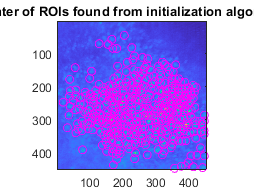

CNM.plotCenters()           % plot center of ROIs detected during initialization


%TODO: optionally manually refine here!

CNM.updateSpatial();        % update spatial components

Updated spatial components 


CNM.updateTemporal(0);      % update temporal components (do not deconvolve at this point)

236 out of 400 components updated 
354 out of 400 components updated 
394 out of 400 components updated 
400 out of 400 components updated 
236 out of 400 components updated 
354 out of 400 components updated 
394 out of 400 components updated 
400 out of 400 components updated 



%TODO: optionally component classification here. ML toolbox needed! 
CNM.evaluateComponents();   % evaluate spatial components based on their correlation with the data
CNM.CNNClassifier('')       % evaluate spatial components with the CNN classifier
CNM.eventExceptionality();  % evaluate traces
CNM.keepComponents();       % keep the components that are above certain thresholds

CNM.merge();
CNM.displayMerging();


%repeat processing
CNM.updateSpatial();

Updated spatial components 


CNM.updateTemporal(); % This time use p in options of CNMF object

139 out of 148 components updated 
148 out of 148 components updated 
139 out of 148 components updated 
148 out of 148 components updated 




%FIXME: in CNMF.extractDFF(), F0 is set as second property, not Df.
%extract_df_f() is commented out, and detrend_df_f() is used. In
%plot_components_GUI_modifiedByNico, Df is found by running extract_df_f().
%So do the same here.
CNM.extractDFF(); %get C_df and F0
[CNM.C_df, CNM.Df] = extract_DF_F(CNM.Y, CNM.A, CNM.C, CNM.P, CNM.options); %get (unused C_df and) Df.

%do some plotting
%figure;
%CNM.plotContours();
%CNM.plotComponentsGUI();     % display all components
%TODO: in csem.m, which does roughly the same steps as this section, there
%is a mysterious Y_r that replaces Y. It originates in plot_components_GUI.
%what is it?

%Apparently, backgrounds (CNM.b) is a flattened 2d matrix, no temporal
%component. (in the case of 30-30-30-30 crop factor, 452*452 = 204304 x 1
%array.
%One entry that is weird is Df, which is empty at this point!

%FIXME: ariable 'CNM' originally saved as a CNMF cannot be instantiated as
%an object and will be read in as a uint32.
CNM_struct = struct(CNM);

save([DATA_PATH OUTPUT_FILE_NAME 'CaUpd.mat'], 'CNM_struct', '-v7.3','-nocompression'); %contains Ca data, so large file
save([DATA_PATH OUTPUT_FILE_NAME 'mocoUpd.mat'], 'options_moco', '-v7.3','-nocompression'); % save the options. small file

%If save was successful, clear the struct copy
clear CNM_struct;
% To load CNM_struct into the workspace, use:
% load([DATA_PATH OUTPUT_FILE_NAME 'CaUpd.mat']); %contains Ca data, so large file
% load([DATA_PATH OUTPUT_FILE_NAME 'mocoUpd.mat']);

%% Custom analysis
%FIXME: divcells.m uses "raw" property to keep CNMF data so far.
%divcellsCNMF, in contrast, does not mess up object properties (by adding
%raw field, as adding custom fields to an instance of a class is illegal in Matlab), but modifies the CNMF data,
%possibly resulting in incompatible data sizes (this was the first
%experience, at least)
%[cID, thresh] = sort_components(CNM); %seems not to change CMN object
%CNM = divcellsCNMF(CNM, cID, thresh); 
%[S_norm, S_bin] = canormCNMF(CNM, thresh);

[belt_struct, belt_scn] = beltProcessPipeline(DATA_PATH, FNAME_LABVIEW(1:end-4), FNAME_NIKDATA(1:end-4)); %remove '.txt' from end of file names

Reading Nikon time stamp file: D:\T301\T301_tmev_d1\T301_tmev_d1.270820.1131_nik.txt
openLabViewData: checking if exists: D:\T301\T301_tmev_d1\T301_tmev_d1.270820.1131.txt
Reading belt file: D:\T301\T301_tmev_d1\T301_tmev_d1.270820.1131.txt
Reading belt time stamps file: D:\T301\T301_tmev_d1\T301_tmev_d1.270820.1131time.txt
Size of galvo: 0  1; reso: 17905      1
Reso is longer, choosing it
Missed frames: 73
No cycles missed
NisElements timestamps used
Movie length: 19.6666 min
Frequency: 15.2357 Hz
Belt length data not provided. Assuming 1.5 m 3 zones.
       17978



%save([DATA_PATH 'v1_workspace.mat'], '-v7.3','-nocompression'); %Large file! To compare results of updated functions with original pipeline

%TODO: use motion_metrics to get some feedback on MoCo. Use
%demo_CajalCourse 2017 in Caiman-matlab/use-cases
%TODO: use bulk processing (check Martin/Nico code with the weird bulk
%parameter)
%TODO: save processed data only.

%Useful: CNMF.plotContours()

% Save processed data part of CNM
%Save A, b, C, f, S, bl, c1, g, neuron_sn, sn, T, dims, d, cm, Coor,
%contours, options, gSig, P, 

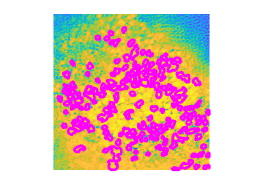

%Plot results along with the corresponding ROI
figure;
CNM.plotContours();

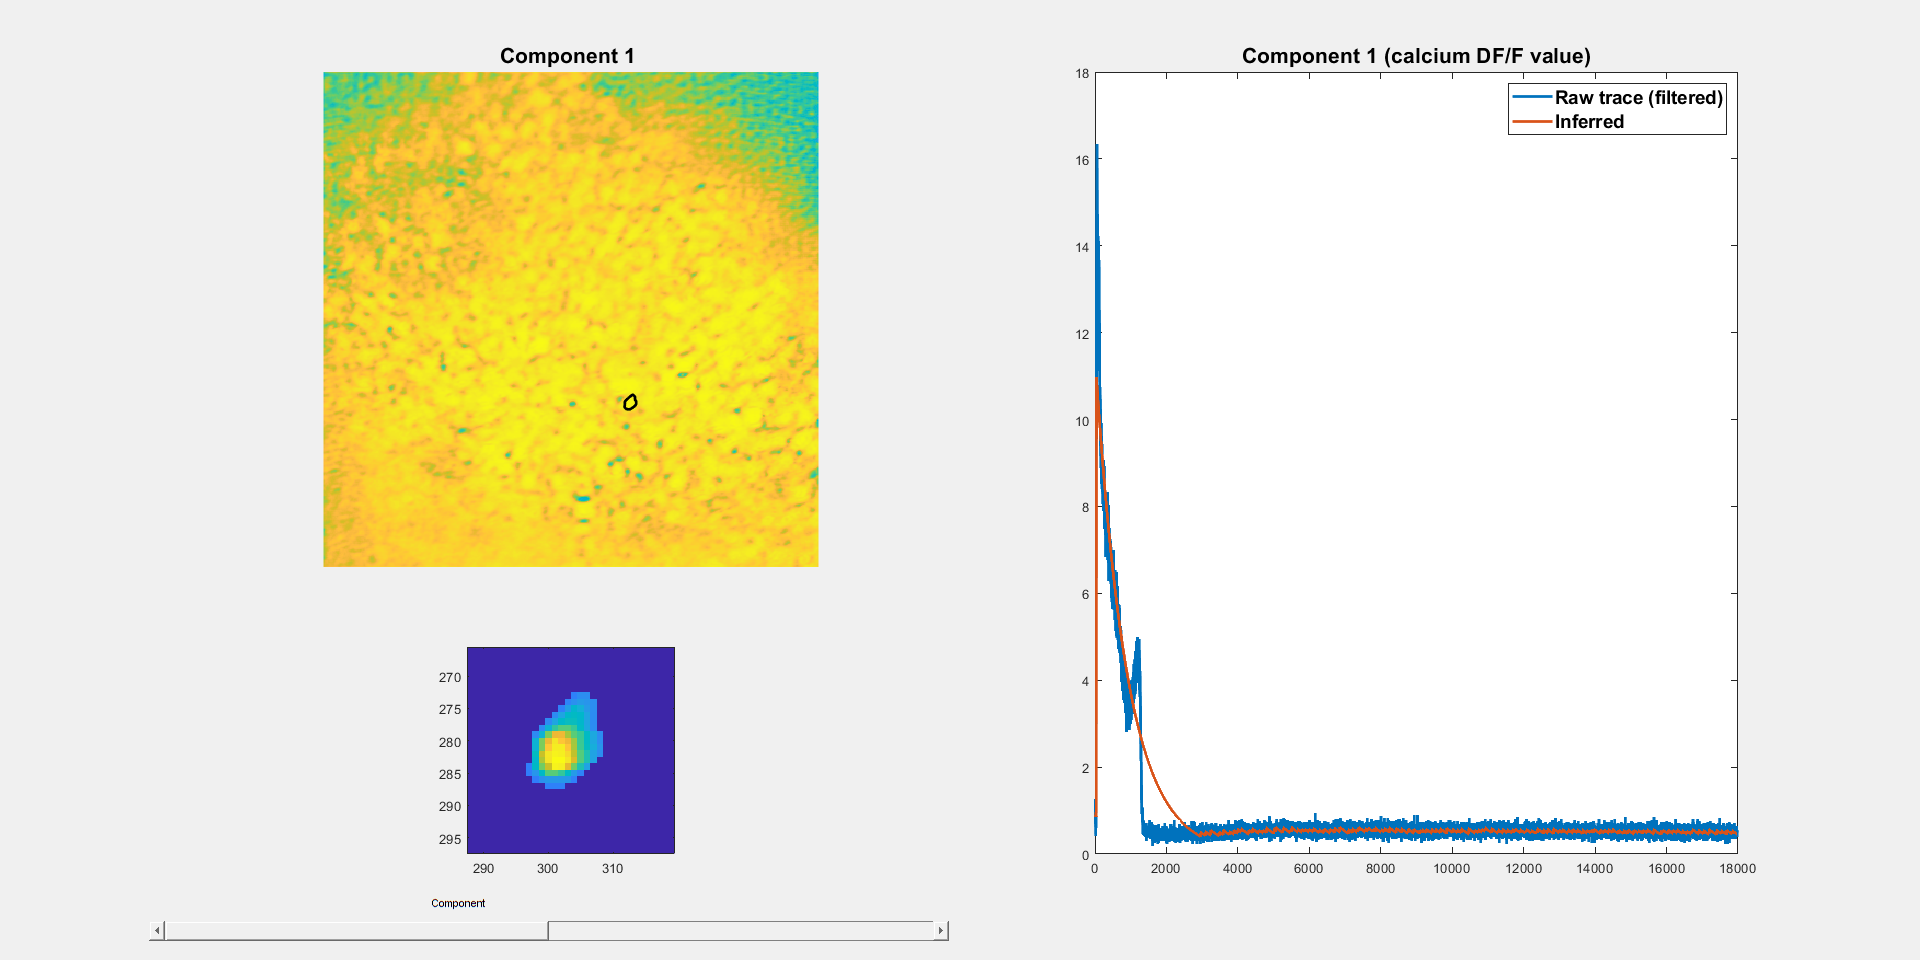

CNM.plotComponentsGUI();     % display all components

%Should watch the residuals and the background, to check if the results are
%good (no cells left behind etc.)
%Y - AC - bf should be noise with no neuropil or cell activity

%AC + bf should be reconstructed movie, maybe save it?


%Save results: The needed stuff is:
% Options (for reproducing analysis if necessary)
% A, C, b, f - spatial and temporal components of cells and background
% Maybe: AC + bf as resulting movie
%

% export fields
fields = fieldnames(CNM)

CNM_struct = struct(CNM)

CNM_struct = struct with fields:
           file: 'D:\T301\T301_tmev_d1\T301_tmev_d1.270820.1131.nd2'
              Y: [452×452×17978 single]
           data: []
             Yr: [204304×17978 single]
             sn: [204304×1 single]
              A: [204304×148 double]
              b: [204304×1 double]
              C: [148×17978 double]
              f: [17.6104 17.3981 17.3761 17.1799 17.1669 17.0763 17.0760 17.2469 17.3100 17.3941 17.4980 17.6317 17.8809 18.0776 18.2873 18.3749 18.7936 18.9362 19.2511 19.6456 19.8902 20.3179 20.8787 21.2603 21.8961 22.4164 23.0915 23.8725 24.6355 … ]
              S: [148×17978 double]
          Y_res: []
              R: [148×17978 double]
             bl: [148×1 double]
             c1: [148×1 double]
              g: {148×1 cell}
      neuron_sn: [148×1 double]
              T: 17978
           dims: [452 452]
              d: 204304
             cm: [400×2 double]
           Coor: []
             Df: [148×1 double]
           C_df: [148×1797